# SEIR Model Simulation

Copyright 2022 The MathWorks, Inc

This is a simple **SEIR** model of disease spread, implemented in MATLAB®. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), and Recovered (R) individuals.

## The Model Overview

The equations that make up the SEIR model are described by 4 ordinary differential equations as follows:


$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}\\
\frac{\textrm{dE}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\textrm{dI}}{\textrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}
\end{array}$$


## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

beta   =0.2 ; % Transmission Rate
gamma  =0.3 ; % Recovery Rate
alpha =0.02;
mu = 0.015;
delta = 0.01; 
I0 = 25;                              % Initial number of infected individuals                               % Initial number of exposed individuals
S0 = 60;                               % Initial number of susceptible individuals
T = 11;                              % Period of 365 days
R0=15;                        % Reproduction number

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

y0 = [S0; I0; R0];                % Initial conditions
tspan = [0 T];                        % Interval of Integration
[t,y] = ode45(@(t,y) sir_model(t,y,beta,gamma,alpha, mu, delta),tspan,y0);

For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

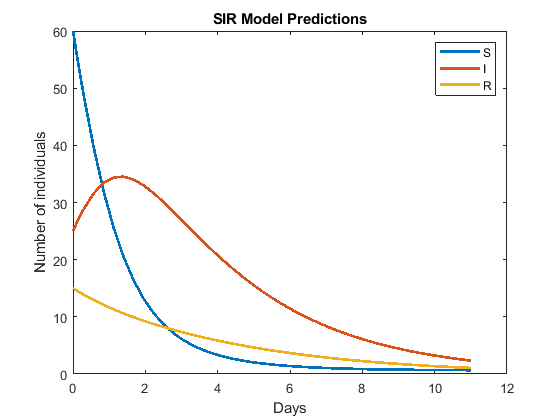

plot(t,y,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('S','I','R');
title('SIR Model Predictions');

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = sir_model(t,y,beta,mu,gamma,alpha, delta)
  S = y(1);
  I = y(2);
  R = y(3);
  % Equations of the model described above
  dS = (-alpha*S*I - mu*S + beta) ;
  dI = (alpha*S*I - (gamma+delta+mu)*I);
  dR = (-mu*R + gamma*I);
  dydt = [dS;dI;dR];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate ($\left.\alpha \right)$, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

-  Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.

  **Task.** Include additional features to your model and observe the effect on the plot.

                Example: To include Immunity loss rate ($\left.\alpha \right)$, the equations will be as follows:

                
$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \frac{I}{N}+\alpha \cdot \mathrm{R}\\
\frac{\textrm{dE}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \frac{I}{N}-\lambda \cdot E\\
\frac{\textrm{dI}}{\textrm{dt}}=\lambda \cdot E-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$
